## Equilibrium curve

a = 5.6;
theta = 0.5;
phi = 15^(1/3);
% xR = 0.001:0.001:0.999;
% x0 = xR(1);
% for i = 1:length(xR)
%     y = 1/2*phi*(xR(i) + 1/phi + 1/(a - 1) - sqrt((xR(i) + 1/phi ...
%             + 1/(a - 1))^2 - (4*a*xR(i))/(phi*(a-1))));
%     alpha = y/(1-y) * (1-xR(i))/xR(i);
%     xF = equilcurve(alpha,theta,x0,xR(i));
%     x0 = xF;
%     yP(i) = (xF - (1-theta)*xR(i))/theta;
% end
% 
% plot(xR,yP,...                  % Plot the equil curve
%     [0,1],[0,1],...             % Plot y = x line
%     "LineWidth",2)
% xlabel('xR');
% ylabel('yP');
% hold on

Counter current

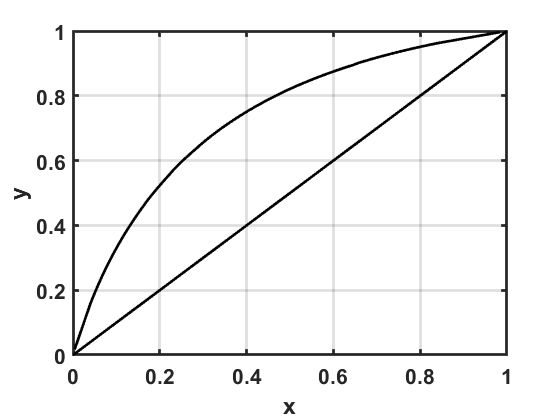

xFs = [0.01,0.1:0.01:0.9,0.99];
for i = 1:length(xFs)
    yPs(i)= counterflow(xFs(i),a,phi,theta);
    xRs(i) = (xFs(i)-theta*yPs(i))/(1-theta);
end

plot([0,1],[0,1],'k',...             % Plot y = x line
    xRs,yPs,'k',...
    "LineWidth",2)
xlabel('x');
ylabel('y');
set(gca,'FontWeight','bold','FontSize',16,'LineWidth',2)
grid on

function xF = equilcurve(alpha,theta,x0,xR)
    options = optimset('Display','off');
    xF = fsolve(@func,x0,options);  
    function dy = func(x)
        dy = log((1-theta)*xR/x)-alpha*log((1-theta)*(1-xR)/(1-x));
    end
end